# Backward optimization and Value function iteration

## Backward optimization

Cake eating problem


$$V_t \left(x_t \right)={\mathrm{max}}_{x_{t+1} } u\left(x_t -x_{t+1} \right)+\beta \;V_{t+1} \left(x_{t+1} \right)\ldotp$$


At the final period:


$$V_T \left(x_T \right)={\mathrm{max}}_{x_{T+1} } u\left(x_T -x_{T+1} \right)=u\left(x_T \right)\ldotp$$


To determine $x_T$, go back one period:


$$V_{T-1} \left(x_{T-1} \right)={\mathrm{max}}_{x_T } \mathrm{ln}\left(x_{T-1} -x_T \right)+\beta \;\mathrm{ln}\left(x_T \right)$$


FOC w.r.t $x_T$ gives: $\frac{1}{x_{T-1} -x_T }=\frac{\beta }{x_T }$ $\iff$ $x_{T\;} =\frac{\beta }{1+\beta \;}x_{T-1} \equiv \phi_T x_{T-1}$.

Hence $V_{T-1} \left(x_{T-1} \right)=\mathrm{ln}\left(\left(1-\phi_T \right)x_{T-1} \right)+\beta \;\mathrm{ln}\left(\phi_T x_{T-1} \right)=\mathrm{cons}+\left(1+\beta \right)\mathrm{ln}\left(x_{T-1} \right)$

To determine $x_{T-1}$, go back one period again:


$$V_{T-2} \left(x_{T-2} \right)={\mathrm{max}}_{x_{T-1} } \mathrm{ln}\left(x_{T-2} -x_{T-1} \right)+\beta \;V_{T-1} \left(x_{T-1} \right)$$


FOC w.r.t $x_{T-1}$ gives: $\frac{1}{x_{T-2} -x_{T-1} }=\frac{\beta +\beta^{2\;} }{x_{T-1} }$ $\iff$ $x_{T-1} =\frac{\beta +\beta^2 }{1+\beta +\beta^2 }x_{T-2} \equiv \phi_{T-1} x_{T-2}$

Likewise, going back one more period gives $x_{T-2} =\frac{\beta +\beta^2 +\beta^3 }{1+\beta +\beta^2 +\beta^3 }x_{T-3} \equiv \phi_{T-2} x_{T-3}$

If we go back s periods, i.e., at period $T-s$ for $s\leq T-1$ we have:$x_{T-s} =\frac{\beta +\beta^2 +\ldotp \ldotp \ldotp +\beta^{s+1} }{1+\beta +\beta^2 +\ldotp \ldotp \ldotp +\beta^{s+1} }x_{T-\left(s+1\right)} \equiv \phi_{T-s} x_{T-\left(s+1\right)}$

Clearly for $s=T-1$, we can solve for the value of the first state as a function of $x_0$ :

$x_1 =\phi_1 x_0 \;$ where $\phi_1 =\frac{\beta +\ldotp \ldotp \ldotp +\beta^T }{1+\beta +\ldotp \ldotp \ldotp +\beta^T }=\frac{\beta \left(1-\beta^T \right)}{1-\beta^{T+1} }=\frac{\beta -\beta^{T+1} }{{1-\beta }^{T+1} }$

This implies $c_{0\;} =x_0 -x_1 =\left(1-\phi_1 \right)x_0 =\frac{1-\beta }{1-\beta^{T+1} }$

More generally we can solve recursively for the states by noting that

$x_t =\phi_t x_{t-1}$ where $\phi_t =\frac{\beta +\ldotp \ldotp \ldotp +\beta^{T-t+1} }{1+\beta +\ldotp \ldotp \ldotp +\beta^{T-t+1} }=\frac{\beta -\beta^{T-t+2} }{1-\beta^{T-t+2} }$.

and $c_t =x_{t-1} -x_t$.

clear; close all;
T = 100;
x0 = 1000;
beta = 1/(1+0.1);
x = zeros(T+2,1);
x(1) = x0;
c = zeros(T+2,1);
T = 100;
for t=1:T+1
    phi_t = (beta-beta^(T-t+2))/(1-beta^(T-t+2));
    x(t+1) = phi_t*x(t);
    c(t) = x(t)-x(t+1);
end


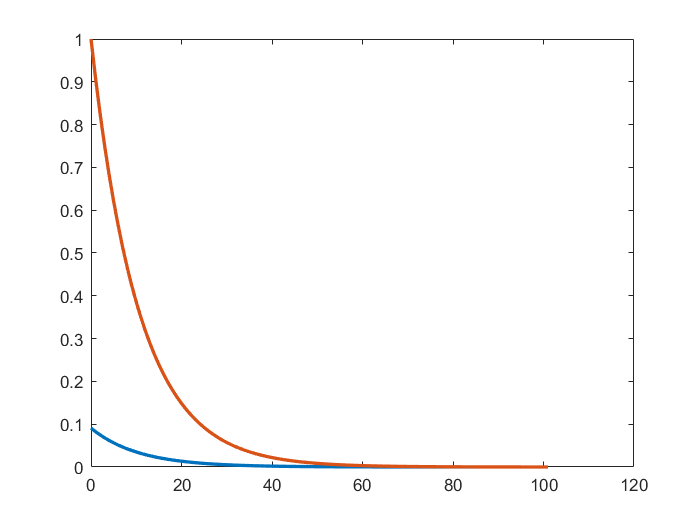

plot(0:T+1,c/x0, 'LineWidth',2)
hold on
plot(0:T+1,x/x0, 'LineWidth',2)
hold off

## Value function iteration

clear all; close all

%% Parameters setting and initialization
horizon=100;

X0=1000;

Save_VF=zeros(X0+1,horizon+1);

Save_conso=zeros(X0+1,horizon+1);

VF=zeros(X0+1,2);        % set the value function to 0 (i.e. V_{T+1})


Code the Bellman operator

% edit Bellman
% inside write the Bellman function then save
% function [NV]=Bellman(VF)
% 
% delta=0.1;
% 
% for state=1:size(VF,1)  % corresponding to X in [0,100]
% 
% consos=0:state-1;       % admissible consumption levels: c in [0,X]
% 
% [m,n]=max(log(consos')+(1/(1+delta))*VF(state-consos,1));
% 
% NV(state,:)=[m,consos(n)];
% 
% end
% 
% end

Value function iteration


for i=1:horizon+1 % loop for iterations

    NV=Bellman(VF);

    Save_VF(:,horizon+2-i)=NV(:,1);

    Save_conso(:,horizon+2-i)=NV(:,2);

    VF=NV;

end
 
time=0:horizon+1;

TRAJ_X=zeros(1,horizon+2);

TRAJ_c=zeros(1,horizon+2);

TRAJ_X(1,1)=X0;

for i=1:horizon+1 % loop for iterations

        TRAJ_c(1,i)=Save_conso(TRAJ_X(1,i),i);

        TRAJ_X(1,i+1)=TRAJ_X(1,i)-TRAJ_c(1,i);

end

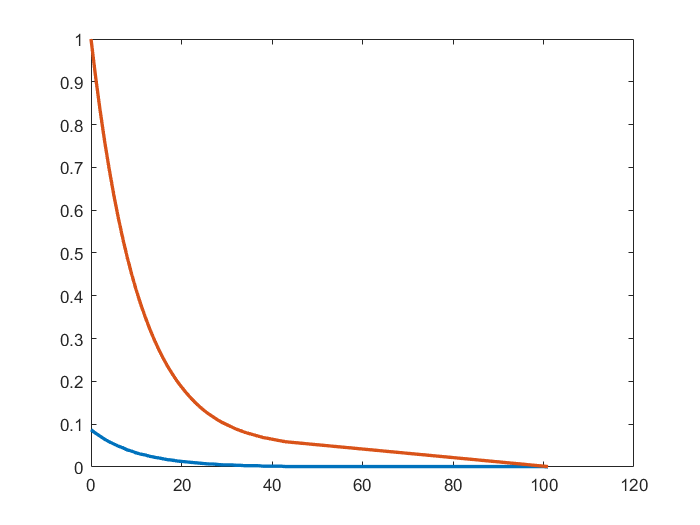


% Plotting of optimal consumption plan and state trajectory
plot(time,TRAJ_c./X0, 'LineWidth', 2)
hold on
plot(time,TRAJ_X/X0, 'LineWidth', 2)
hold off